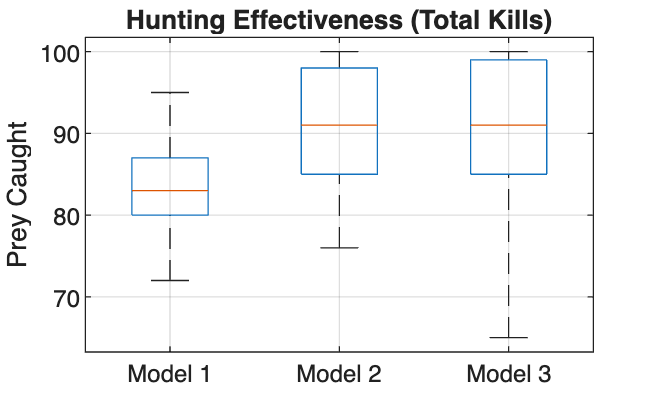

clear; clc;

% Read the results file 
T = readtable('benchmark_results_withdistance.csv');

% Split data into the three models
model1 = T(contains(T.simulation_id, 'method1'), :);
model2 = T(contains(T.simulation_id, 'method2'), :);
model3 = T(contains(T.simulation_id, 'method3'), :);

% Colors
colors = [0 0.4470 0.7410; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880];

% Calculate Efficiency: Catches per 1000px travelled
model1.Efficiency = (model1.boids_caught ./ model1.avg_total_distance_traveled) * 1000;
model2.Efficiency = (model2.boids_caught ./ model2.avg_total_distance_traveled) * 1000;
model3.Efficiency = (model3.boids_caught ./ model3.avg_total_distance_traveled) * 1000;

% Combine back into one array
all_efficiency = [model1.Efficiency; model2.Efficiency; model3.Efficiency];
group_labels = [repmat("Model 1", height(model1), 1); ...
                repmat("Model 2", height(model2), 1); ...
                repmat("Model 3", height(model3), 1)];

% Plot 1 Effectiveness (Kill Count)

figure('Name', 'Effectiveness', 'Color', 'w');

boxplot(T.boids_caught, group_labels);

title('Hunting Effectiveness (Total Kills)');

ylabel('Prey Caught');

grid on;

saveas(gcf, 'Plot1_Catch_Count.png');

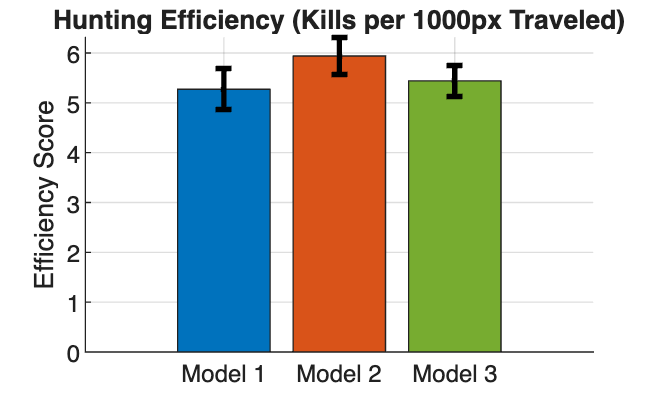

% Plot 2 Effectiveness (Energy Consumed)
figure('Name', 'Efficiency', 'Color', 'w');

% Calculate means and standard deviations
means = [mean(model1.Efficiency), mean(model2.Efficiency), mean(model3.Efficiency)];
stds  = [std(model1.Efficiency),  std(model2.Efficiency),  std(model3.Efficiency)];

hold on;
% Draw bars
b = bar(means, 'FaceColor', 'flat');
b.CData = colors;
% Draw error bars
errorbar(1:3, means, stds, 'k.', 'LineWidth', 2);
hold off;

title('Hunting Efficiency (Kills per 1000px Traveled)');
ylabel('Efficiency Score');
xticks(1:3);
xticklabels({'Model 1', 'Model 2', 'Model 3'});
grid on;
saveas(gcf, 'Plot2_Efficiency.png');

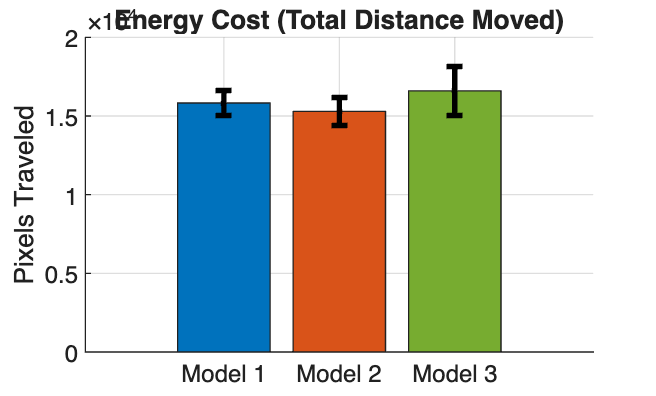

% Plot 3: Energy Cost (Distance Traveled)
figure('Name', 'Energy Cost', 'Color', 'w');

% Calculate means and standard deviations for Distance
means_dist = [mean(model1.avg_total_distance_traveled), ...
              mean(model2.avg_total_distance_traveled), ...
              mean(model3.avg_total_distance_traveled)];

stds_dist  = [std(model1.avg_total_distance_traveled), ...
              std(model2.avg_total_distance_traveled), ...
              std(model3.avg_total_distance_traveled)];

hold on;
% Draw bars
b = bar(means_dist, 'FaceColor', 'flat');
b.CData = colors; % Uses the same colors defined previously

% Draw error bars
errorbar(1:3, means_dist, stds_dist, 'k.', 'LineWidth', 2);
hold off;

% Force the ticks to align with the bars
xticks(1:3);
xticklabels({'Model 1', 'Model 2', 'Model 3'});

title('Energy Cost (Total Distance Moved)');
ylabel('Pixels Traveled');
grid on;

% Save the figure
saveas(gcf, 'Plot3_Energy_Cost.png');

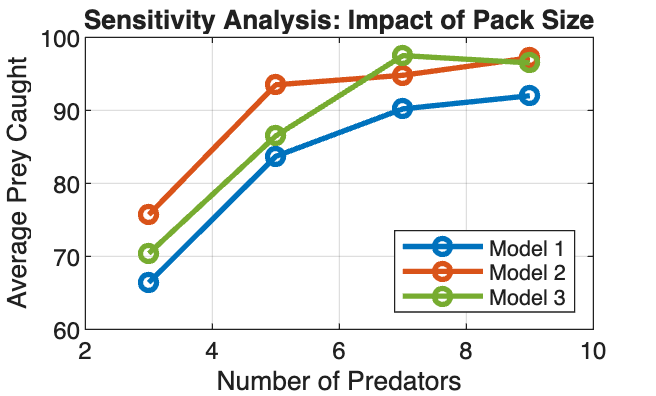

% Analysing Sensitivity usin Predator Count
files = {'benchmark_results_3predators.csv', 'benchmark_results_5predators.csv', ...
         'benchmark_results_7preds.csv', 'benchmark_results_9predators.csv'};
predator_counts = [3, 5, 7, 9];

% Pre-allocate arrays to store the averages for each model
avg_m1 = zeros(1, 4);
avg_m2 = zeros(1, 4);
avg_m3 = zeros(1, 4);

% Loop through each file to calculate the mean catch
for i = 1:4
    data = readtable(files{i});
    
    % Filter by method and calculate mean catch
    m1 = data(contains(data.simulation_id, 'method1'), :);
    m2 = data(contains(data.simulation_id, 'method2'), :);
    m3 = data(contains(data.simulation_id, 'method3'), :);
    
    avg_m1(i) = mean(m1.boids_caught);
    avg_m2(i) = mean(m2.boids_caught);
    avg_m3(i) = mean(m3.boids_caught);
end

% Plot lines
figure('Name', 'Sensitivity', 'Color', 'w');
plot(predator_counts, avg_m1, '-o', 'LineWidth', 2, 'Color', colors(1,:)); hold on;
plot(predator_counts, avg_m2, '-o', 'LineWidth', 2, 'Color', colors(2,:));
plot(predator_counts, avg_m3, '-o', 'LineWidth', 2, 'Color', colors(3,:));
hold off;

title('Sensitivity Analysis: Impact of Pack Size');
xlabel('Number of Predators');
ylabel('Average Prey Caught');
legend({'Model 1', 'Model 2', 'Model 3'}, 'Location', 'southeast');
grid on;
saveas(gcf, 'Plot4_Sensitivity.png');

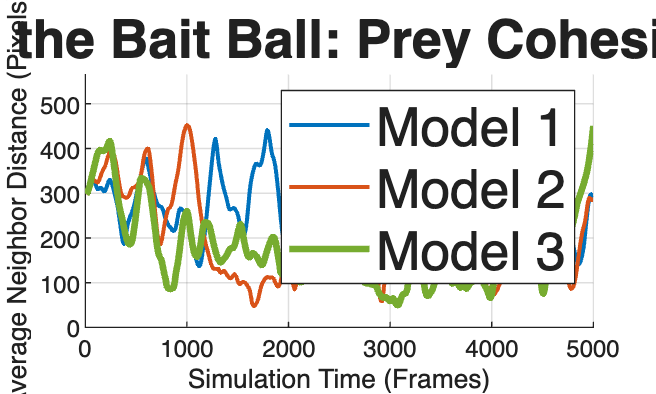

%% 1. Load Data
clear; clc; close all;

% Read the time-series data
T = readtable('cohesion_timeseries_3_predators.csv');

% Define Colors (Blue, Orange, Green)
colors = [0 0.4470 0.7410; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880];

%% 2. Create Time-Series Plot
figure('Name', 'Cohesion Dynamics', 'Color', 'w', 'Position', [100, 100, 1000, 600]);

hold on;

% Plot Model 1 (Herding) - Dashed/Thinner (Baseline)
p1 = plot(T.frame, T.model1_herding_cohesion, 'LineWidth', 1.5, ...
    'Color', colors(1,:));

% Plot Model 2 (Hybrid) - Dotted (Intermediate)
p2 = plot(T.frame, T.model2_intercept_cohesion, 'LineWidth', 1.5, ...
    'Color', colors(2,:));

% Plot Model 3 (Coordination) - Solid/Thick (Main Result)
p3 = plot(T.frame, T.model3_coordination_cohesion, 'LineWidth', 2.5, ...
    'Color', colors(3,:));

% Add a "Bait Ball Threshold" reference line (optional, based on your visual observation)
% yline(150, 'k-.', 'Bait Ball Threshold', 'LabelHorizontalAlignment', 'left');

hold off;

%% 3. Formatting
title('Formation of the Bait Ball: Prey Cohesion Over Time', 'FontSize',20);
xlabel('Simulation Time (Frames)');
ylabel('Average Neighbor Distance (Pixels)');
lgd = legend([p1, p2, p3], {'Model 1', 'Model 2', 'Model 3'}, ...
    'Location', 'northeast');

lgd.FontSize = 20;

% Invert Y axis? No, lower distance = tighter ball, so lower is "better" for bait ball.
% We usually want "better" to be intuitive.
% Let's keep it standard: Lower Y = Tighter Packing.

grid on;
xlim([0 max(T.frame)]);
ylim([0 max([T.model1_herding_cohesion; T.model2_intercept_cohesion]) + 50]);

% Add annotations if Model 3 drops significantly
% (You can adjust these coordinates based on the plot)
% text(1000, 100, 'Coordinated Compression', 'Color', colors(3,:), 'FontWeight', 'bold');

saveas(gcf, 'Figure_Cohesion_TimeSeries.png');